%Community Solar Billing Simulator - Project 1%
%Benjamin Oakes - Engineering Computer Applications%

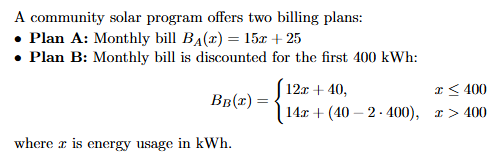

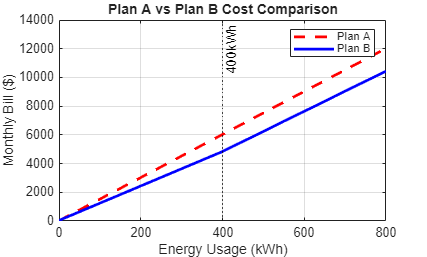

x = 0:25:800; 
%Billing plan A equation%
Plan_A = 15 * x + 25; 
%Billing plan B equation, including the change at x=400%
Plan_B = (12 * x + 40) .* (x <= 400) + (14 * x - 760) .* (x > 400); 

figure; 
%Plots the plan A equation%
% The r-- inside the plot command represents making plan A a red dashed
% line%
plot(x, Plan_A, 'r--', 'LineWidth', 2); hold on; 
%Plots the plan B equation%
%The b- inside the plot command represents making plan B a solid blue line%
plot(x, Plan_B, 'b-', 'LineWidth', 2); 
%Creates a break at x=400, showing when the equation of plan B shifts to
%the next part%
xline(400, 'k:', '400kWh'); 
%Displays grid lines%
grid on; 
%Labels x axis%
xlabel('Energy Usage (kWh)'); 
%Labels y axis%
ylabel('Monthly Bill ($)'); 
%Creates title for the plot%
title('Plan A vs Plan B Cost Comparison'); 
%Creates a legend to identify functions%
legend('Plan A', 'Plan B'); 

%Creates lines on the x axis in increments of 5 until value reaches 800, increments of 5 were chosen to find a value where Plan A and Plan B had the same cost%
energy_usage = (0:5:800)'; 
%Plugs in the increments of 5 into the plan A equation to get a value at
%each specific x value%
Plan_A = 15 * energy_usage + 25; 
%Plugs in the increments of 5 into the plan B equation to get a value at
%each specific x value%
Plan_B = (12 * energy_usage + 40) .* (energy_usage <= 400) + (14 * energy_usage - 760) .* (energy_usage > 400);

(14 * energy_usage - 760) .* (energy_usage > 400); 
%Names the subjects%
TableResults = table(energy_usage, Plan_A, Plan_B);
%Organizes the subjects inside the table%
'VariableNames', {'Usage_kWh', 'Plan_A', 'Plan_B'}; 

ans = 'VariableNames'

%Displays the table%
disp(TableResults); 

    energy_usage    Plan_A    Plan_B
    ____________    ______    ______

          0            25        40 
          5           100       100 
         10           175       160 
         15           250       220 
         20           325       280 
         25           400       340 
         30           475       400 
         35           550       460 
         40           625       520 
         45           700       580 
         50           775       640 
         55           850       700 
         60           925       760 
         65          1000       820 
         70          1075       880 
         75          1150       940 
         80          1225      1000 
         85          1300      1060 
         90          1375      1120 
         95          1450      1180 
        100          1525      1240 
        105          1600      1300 
        1


%Anytime after 5 watts, Plan B will be cheaper%
%At 5 watts Plan A and Plan B will have the same cost%
